Mouse_ID = ["112",
            "109",
            "111"]

Mouse_ID = 3×1 string array
    "112"
    "109"
    "111"



Mouse_ID = ["112",
            "109"]

Mouse_ID = 2×1 string array
    "112"
    "109"


summary_path = '/Users/pingchuanma/Desktop/ChenLab_Data/FLP_data_sleep/ACh_mut/'

summary_path = '/Users/pingchuanma/Desktop/ChenLab_Data/FLP_data_sleep/ACh_mut/'

cd(summary_path)

datapath = {"/Users/pingchuanma/Desktop/ChenLab_Data/FLP_data_sleep/ACh_mut/20220422_112_AChmtut_SW_001_analysis_csv_20220426/results/",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/FLP_data_sleep/ACh_mut/20220425_109_AChmut_SW_001_analysis_csv_20220510/results/",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/FLP_data_sleep/ACh_mut/20220712_PM29_111_Achmut_001_analysis_csv_20220830/results/"}

datapath = 1×3 cell array
    {["/Users/pingchuanma/Desktop/ChenLab_Data/FLP_data_sleep/ACh_mut/20220422_112_AChmtut_SW_001_analysis_csv_20220426/results/"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/FLP_data_sleep/ACh_mut/20220425_109_AChmut_SW_001_analysis_csv_20220510/results/"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/FLP_data_sleep/ACh_mut/20220712_PM29_111_Achmut_001_analysis_csv_20220830/results/"]}



datapath = {"/Users/pingchuanma/Desktop/ChenLab_Data/FLP_data_sleep/ACh_mut/20220206_112_8_AChMut_SW_001_analysis_csv_20220510/results/",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/FLP_data_sleep/ACh_mut/20220207_109_AChMut_SW_001_analysis_csv_20220510/results/"}

datapath = 1×2 cell array
    {["/Users/pingchuanma/Desktop/ChenLab_Data/FLP_data_sleep/ACh_mut/20220206_112_8_AChMut_SW_001_analysis_csv_20220510/results/"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/FLP_data_sleep/ACh_mut/20220207_109_AChMut_SW_001_analysis_csv_20220510/results/"]}


% intensity_all = [];
% mouse_all = [];
% time_all = [];
% states_all = [];
% lft_all = [];
% time1_all = [];
% time2_all = [];


for i=1:2

        cd(datapath{i})

    for k = 1:4

        eval(['time1_csv = "time',num2str(k),'_1.csv"'])
        column_name = ['0']
        [time1] = csvimport(convertStringsToChars(time1_csv), 'columns', {column_name}, 'noHeader', false);
        class_check = class(time1);
        if class_check(1) == 'c'
            time1 = str2double(time1);
        end
        time1(find(isnan(time1) == 1)) = [];
        eval(['time1_',convertStringsToChars(Mouse_ID(i)),'_',num2str(k),'= time1;']);

        eval(['time2_csv = "time',num2str(k),'_2.csv"'])
        column_name = ['1']
        [time2] = csvimport(convertStringsToChars(time2_csv), 'columns', {column_name}, 'noHeader', false);
        class_check = class(time2);
        if class_check(1) == 'c'
            time2 = str2double(time2);
        end
        time2(find(isnan(time2) == 1)) = [];
        eval(['time2_',convertStringsToChars(Mouse_ID(i)),'_',num2str(k),'= time2;']);

        ignored_index = find(time1 <= 10800);
       

        eval(['intensity_csv = "intensity',num2str(k),'.csv"'])
        column_name = ['state',num2str(k)]
        [intensity] = csvimport(convertStringsToChars(intensity_csv), 'columns', {column_name}, 'noHeader', false);
        class_check = class(intensity);
        if class_check(1) == 'c'
            intensity = str2double(intensity);
        end


        intensity(find(isnan(intensity) == 1)) = [];
        intensity(ignored_index) = [];
        intensity = intensity/100000;


        eval(['intensity_',convertStringsToChars(Mouse_ID(i)),'_',num2str(k),'= intensity;']);

        eval(['lft_csv = "lft',num2str(k),'.csv"'])
        column_name = ['state',num2str(k)]
        [lft] = csvimport(convertStringsToChars(lft_csv), 'columns', {column_name}, 'noHeader', false);
        class_check = class(lft);
        if class_check(1) == 'c'
            lft = str2double(lft);
        end
        lft(find(isnan(lft) == 1)) = [];
        lft(ignored_index) = [];
        eval(['lft_',convertStringsToChars(Mouse_ID(i)),'_',num2str(k),'= lft;']);

%         lft_all = [lft_all;lft];
%         intensity_all = [intensity_all;intensity];
%         mouse_all = [mouse_all; zeros(length(intensity),1)+str2num(Mouse_ID(i))];
%         time_all = [time_all; zeros(length(intensity),1)+j];
%         states_all = [states_all; zeros(length(intensity),1)+k];

    end



end

time1_csv = "time1_1.csv"

column_name = '0'

time2_csv = "time1_2.csv"

column_name = '1'

intensity_csv = "intensity1.csv"

column_name = 'state1'

lft_csv = "lft1.csv"

column_name = 'state1'

time1_csv = "time2_1.csv"

column_name = '0'

time2_csv = "time2_2.csv"

column_name = '1'

intensity_csv = "intensity2.csv"

column_name = 'state2'

lft_csv = "lft2.csv"

column_name = 'state2'

time1_csv = "time3_1.csv"

column_name = '0'

time2_csv = "time3_2.csv"

column_name = '1'

intensity_csv = "intensity3.csv"

column_name = 'state3'

lft_csv = "lft3.csv"

column_name = 'state3'

time1_csv = "time4_1.csv"

column_name = '0'

time2_csv = "time4_2.csv"

column_name = '1'

intensity_csv = "intensity4.csv"

column_name = 'state4'

lft_csv = "lft4.csv"

column_name = 'state4'

time1_csv = "time1_1.csv"

column_name = '0'

time2_csv = "time1_2.csv"

column_name = '1'

intensity_csv = "intensity1.csv"

column_name = 'state1'

lft_csv = "lft1.csv"

column_name = 'state1'

time1_csv = "time2_1.csv"

column_name = '0'

time2_csv = "time2_2.csv"

column_name = '1'

intensity_csv = "intensity2.csv"

column_name = 'state2'

lft_csv = "lft2.csv"

column_name = 'state2'

time1_csv = "time3_1.csv"

column_name = '0'

time2_csv = "time3_2.csv"

column_name = '1'

intensity_csv = "intensity3.csv"

column_name = 'state3'

lft_csv = "lft3.csv"

column_name = 'state3'

time1_csv = "time4_1.csv"

column_name = '0'

time2_csv = "time4_2.csv"

column_name = '1'

intensity_csv = "intensity4.csv"

column_name = 'state4'

lft_csv = "lft4.csv"

column_name = 'state4'

sleep_index = find(states_all == 2 | states_all == 3);
intensity_all_sleep = intensity_all(sleep_index);
lft_all_sleep = lft_all(sleep_index);
mouse_all_sleep = mouse_all(sleep_index);
time_all_sleep = time_all(sleep_index);
states_all_sleep = states_all(sleep_index);


remove_index1 =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


remove_index2 =    253
   254
   255
   256
   257
   258
   259
   260
   261
   262


mouse_all_categorical = categorical(mouse_all);
time_all_categorical = categorical(time_all);
states_all_categorical = categorical(states_all);

categories(mouse_all_categorical)

ans = 7×1 cell array
    {'1610'}
    {'1611'}
    {'1612'}
    {'1626'}
    {'1627'}
    {'1629'}
    {'1630'}


categories(time_all_categorical)

ans = 3×1 cell array
    {'1'}
    {'2'}
    {'3'}


categories(states_all_categorical)

ans = 4×1 cell array
    {'1'}
    {'2'}
    {'3'}
    {'4'}



mouse_all_sleep_categorical = categorical(mouse_all_sleep);
time_all_sleep_categorical = categorical(time_all_sleep);
states_all_sleep_categorical = categorical(states_all_sleep);

categories(mouse_all_sleep_categorical)

ans = 7×1 cell array
    {'1610'}
    {'1611'}
    {'1612'}
    {'1626'}
    {'1627'}
    {'1629'}
    {'1630'}


categories(time_all_sleep_categorical)

ans = 3×1 cell array
    {'1'}
    {'2'}
    {'3'}


categories(states_all_sleep_categorical)

ans = 2×1 cell array
    {'2'}
    {'3'}


lft_table = table(mouse_all_categorical, time_all_categorical, states_all_categorical, lft_all)

intensity_table = table(mouse_all_categorical, time_all_categorical, states_all_categorical, intensity_all)

mdl1=stepwiseglm(lft_table,'constant','Criterion','adjrsquared')

1. Adding states_all_categorical, AdjRsquared = 0.34343
2. Adding mouse_all_categorical, AdjRsquared = 0.60887
3. Adding time_all_categorical, AdjRsquared = 0.64935
4. Adding mouse_all_categorical:time_all_categorical, AdjRsquared = 0.75077
5. Adding mouse_all_categorical:states_all_categorical, AdjRsquared = 0.77256
6. Adding time_all_categorical:states_all_categorical, AdjRsquared = 0.77415


mdl1 = Generalized linear regression model:
    lft_all ~ 1 + mouse_all_categorical*time_all_categorical + mouse_all_categorical*states_all_categorical + time_all_categorical*states_all_categorical
    Distribution = Normal

Estimated Coefficients:
                                                                 Estimate                  SE                   tStat                  pValue       
                                                           ____________________    ___________________    __________________    ____________________

    (Intercept)                                                 4.1983290457742    0.00233713353701478      1796.35822227631                       0
    mouse_all_categorical_1611                               0.0117971614486963    0.00356691333121951      3.30738662625787    0.000

mdl2=stepwiseglm(intensity_table,'constant','Criterion','adjrsquared')

1. Adding mouse_all_categorical, AdjRsquared = 0.51962
2. Adding time_all_categorical, AdjRsquared = 0.8
3. Adding mouse_all_categorical:time_all_categorical, AdjRsquared = 0.97618
4. Adding states_all_categorical, AdjRsquared = 0.99136
5. Adding mouse_all_categorical:states_all_categorical, AdjRsquared = 0.99362
6. Adding time_all_categorical:states_all_categorical, AdjRsquared = 0.99392


mdl2 = Generalized linear regression model:
    intensity_all ~ 1 + mouse_all_categorical*time_all_categorical + mouse_all_categorical*states_all_categorical + time_all_categorical*states_all_categorical
    Distribution = Normal

Estimated Coefficients:
                                                                Estimate                  SE                  tStat                  pValue        
                                                           ___________________    __________________    __________________    _____________________

    (Intercept)                                               1.39220696520211    0.0100866612682654      138.024558193727                        0
    mouse_all_categorical_1611                              -0.186517495069529     0.015394176659339      -12.116107226584     7.7

lft_table_sleep = table(mouse_all_sleep_categorical, time_all_sleep_categorical, states_all_sleep_categorical, lft_all_sleep)
intensity_table_sleep = table(mouse_all_sleep_categorical, time_all_sleep_categorical, states_all_sleep_categorical, intensity_all_sleep)

sleep_wake_all_table = table(mouse_all_sleep_categorical, time_all_sleep_categorical, states_all_sleep_categorical, lft_all_sleep, intensity_all_sleep)

mdl3=stepwiseglm(lft_table_sleep,'constant','Criterion','adjrsquared')

1. Adding states_all_sleep_categorical, AdjRsquared = 0.49593
2. Adding mouse_all_sleep_categorical, AdjRsquared = 0.72898
3. Adding time_all_sleep_categorical, AdjRsquared = 0.76619
4. Adding mouse_all_sleep_categorical:time_all_sleep_categorical, AdjRsquared = 0.87259
5. Adding mouse_all_sleep_categorical:states_all_sleep_categorical, AdjRsquared = 0.87864
6. Adding time_all_sleep_categorical:states_all_sleep_categorical, AdjRsquared = 0.87875


mdl3 = Generalized linear regression model:
    lft_all_sleep ~ 1 + mouse_all_sleep_categorical*time_all_sleep_categorical + mouse_all_sleep_categorical*states_all_sleep_categorical + time_all_sleep_categorical*states_all_sleep_categorical
    Distribution = Normal

Estimated Coefficients:
                                                                        Estimate         SE          tStat        pValue  
                                                                       ___________    _________    _________    __________

    (Intercept)                                                             4.1354    0.0059133       699.34             0
    mouse_all_sleep_categorical_1611                                      0.005543    0.0067128      0.82574        0.4092
    mouse_all_sleep_categorical_1612  

mdl4=stepwiseglm(intensity_table_sleep,'constant','Criterion','adjrsquared')

1. Adding mouse_all_sleep_categorical, AdjRsquared = 0.65002
2. Adding time_all_sleep_categorical, AdjRsquared = 0.80507
3. Adding mouse_all_sleep_categorical:time_all_sleep_categorical, AdjRsquared = 0.9765
4. Adding states_all_sleep_categorical, AdjRsquared = 0.99291
5. Adding mouse_all_sleep_categorical:states_all_sleep_categorical, AdjRsquared = 0.99653
6. Adding time_all_sleep_categorical:states_all_sleep_categorical, AdjRsquared = 0.99694


mdl4 = Generalized linear regression model:
    intensity_all_sleep ~ 1 + mouse_all_sleep_categorical*time_all_sleep_categorical + mouse_all_sleep_categorical*states_all_sleep_categorical + time_all_sleep_categorical*states_all_sleep_categorical
    Distribution = Normal

Estimated Coefficients:
                                                                       Estimate        SE        tStat        pValue   
                                                                       _________    ________    ________    ___________

    (Intercept)                                                           3.4866    0.021299       163.7              0
    mouse_all_sleep_categorical_1611                                     -2.4289    0.024179     -100.45              0
    mouse_all_sleep_categorical_1612        

cd(datapath)
lft_all_sheet_fromSamarth = 'all_mouse_lft_emp.csv';
intensity_all_sheet_fromSamarth = 'all_mouse_intensity.csv';

lft_tbl_fromSA = readtable(lft_all_sheet_fromSamarth, 'NumHeaderLines', 1)

lft_tbl_fromSA = 812×5 table
    Var1    Var2    Var3    Var4     Var5 
    ____    ____    ____    ____    ______

      0      2       1       1      4.1525
      1      2       1       1      4.1527
      2      2       1       1      4.1536
      3      2       1       1      4.1653
      4      2       1       1      4.1725
      5      2       1       1      4.1756
      6      2       1       1      4.1752
      7      2       1       1       4.173
      8      2       1       1      4.1802
      9      2       1       1      4.1799
     10      2       1       1      4.1831
     11      2       1       1      4.1823
     12      2       1       1      4.1884
     13      2       1       1      4.1898
     14      2       1       1      4.1933
     15      2       1       1      4.1602


intensity_tbl_fromSA = readtable(intensity_all_sheet_fromSamarth, 'NumHeaderLines', 1)

intensity_tbl_fromSA = 812×5 table
    Var1    Var2    Var3    Var4     Var5 
    ____    ____    ____    ____    ______

      0      2       1       1        2.41
      1      2       1       1      2.4254
      2      2       1       1      2.3763
      3      2       1       1      2.3963
      4      2       1       1      2.3903
      5      2       1       1      2.3649
      6      2       1       1      2.3558
      7      2       1       1      2.3662
      8      2       1       1      2.3744
      9      2       1       1       2.369
     10      2       1       1      2.3657
     11      2       1       1      2.3679
     12      2       1       1      2.3645
     13      2       1       1      2.3608
     14      2       1       1      2.3688
     15      2       1       1      2.3735



states_SA = categorical(table2array(lft_tbl_fromSA(:,2)));
time_SA = categorical(table2array(lft_tbl_fromSA(:,3)));
subject_SA = categorical(table2array(lft_tbl_fromSA(:,4)));
lft_SA = table2array(lft_tbl_fromSA(:,5));
intensity_SA = table2array(intensity_tbl_fromSA(:,5));

lft_SA_tbl = table(subject_SA, time_SA, states_SA, lft_SA)

lft_SA_tbl = 812×4 table
    subject_SA    time_SA    states_SA    lft_SA
    __________    _______    _________    ______

        1            1           2        4.1525
        1            1           2        4.1527
        1            1           2        4.1536
        1            1           2        4.1653
        1            1           2        4.1725
        1            1           2        4.1756
        1            1           2        4.1752
        1            1           2         4.173
        1            1           2        4.1802
        1            1           2        4.1799
        1            1           2        4.1831
        1            1           2        4.1823
        1            1           2        4.1884
        1            1           2        4.1898
        1            1           2        4.1933
     

intensity_SA_tbl = table(subject_SA, time_SA, states_SA, intensity_SA)

intensity_SA_tbl = 812×4 table
    subject_SA    time_SA    states_SA    intensity_SA
    __________    _______    _________    ____________

        1            1           2             2.41   
        1            1           2           2.4254   
        1            1           2           2.3763   
        1            1           2           2.3963   
        1            1           2           2.3903   
        1            1           2           2.3649   
        1            1           2           2.3558   
        1            1           2           2.3662   
        1            1           2           2.3744   
        1            1           2            2.369   
        1            1           2           2.3657   
        1            1           2           2.3679   
        1            1           2           2.3645   
       

mdl5=stepwiseglm(lft_SA_tbl,'constant','Criterion','adjrsquared')

1. Adding states_SA, AdjRsquared = 0.49593
2. Adding subject_SA, AdjRsquared = 0.72898
3. Adding time_SA, AdjRsquared = 0.76619
4. Adding subject_SA:time_SA, AdjRsquared = 0.87259
5. Adding subject_SA:states_SA, AdjRsquared = 0.87864
6. Adding time_SA:states_SA, AdjRsquared = 0.87875


mdl5 = Generalized linear regression model:
    lft_SA ~ 1 + subject_SA*time_SA + subject_SA*states_SA + time_SA*states_SA
    Distribution = Normal

Estimated Coefficients:
                                 Estimate         SE         tStat        pValue  
                                ___________    _________    ________    __________

    (Intercept)                      4.1741    0.0036032      1158.4             0
    subject_SA_2                   0.019243    0.0042781       4.498    7.8985e-06
    subject_SA_3                  -0.036738    0.0055072      -6.671    4.8069e-11
    subject_SA_4                  -0.040638     0.004161     -9.7663    2.4537e-21
    subject_SA_5                  -0.033163    0.0048636     -6.8187    1.8381e-11
    subject_SA_

mdl6=stepwiseglm(intensity_SA_tbl,'constant','Criterion','adjrsquared')

1. Adding subject_SA, AdjRsquared = 0.65002
2. Adding time_SA, AdjRsquared = 0.80507
3. Adding subject_SA:time_SA, AdjRsquared = 0.9765
4. Adding states_SA, AdjRsquared = 0.99291
5. Adding subject_SA:states_SA, AdjRsquared = 0.99653
6. Adding time_SA:states_SA, AdjRsquared = 0.99694


mdl6 = Generalized linear regression model:
    intensity_SA ~ 1 + subject_SA*time_SA + subject_SA*states_SA + time_SA*states_SA
    Distribution = Normal

Estimated Coefficients:
                                Estimate        SE        tStat       pValue   
                                _________    ________    _______    ___________

    (Intercept)                    2.3513    0.012979     181.16              0
    subject_SA_2                   0.2503    0.015409     16.243      2.436e-51
    subject_SA_3                 -0.65992    0.019837    -33.267     6.812e-152
    subject_SA_4                 -0.79067    0.014988    -52.755    7.8387e-260
    subject_SA_5                  -1.2935    0.017518    -73.838              0
    subject_SA_6            </

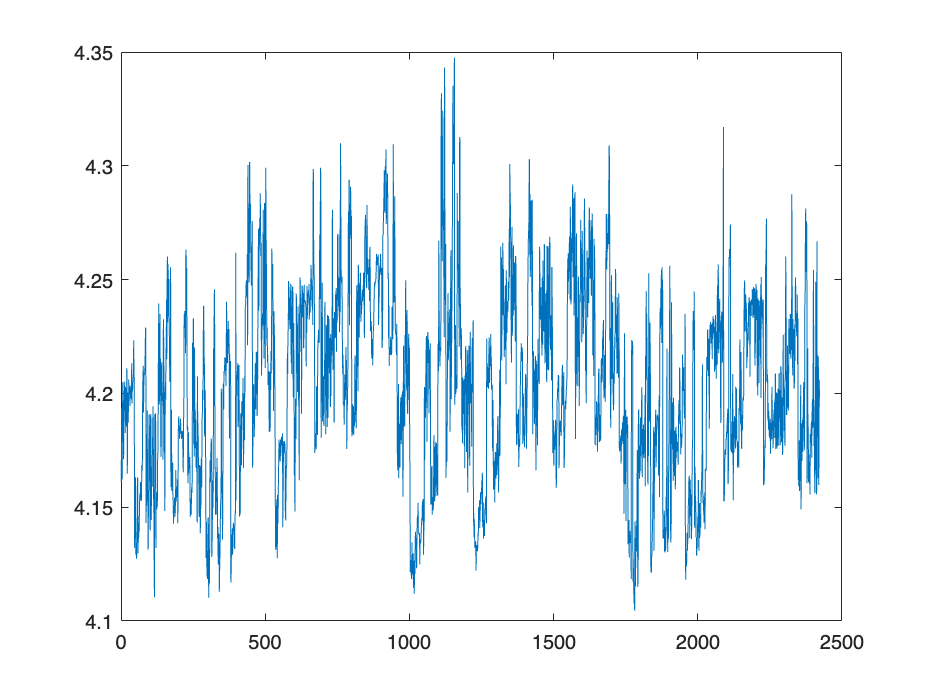

figure
plot(lft_all)

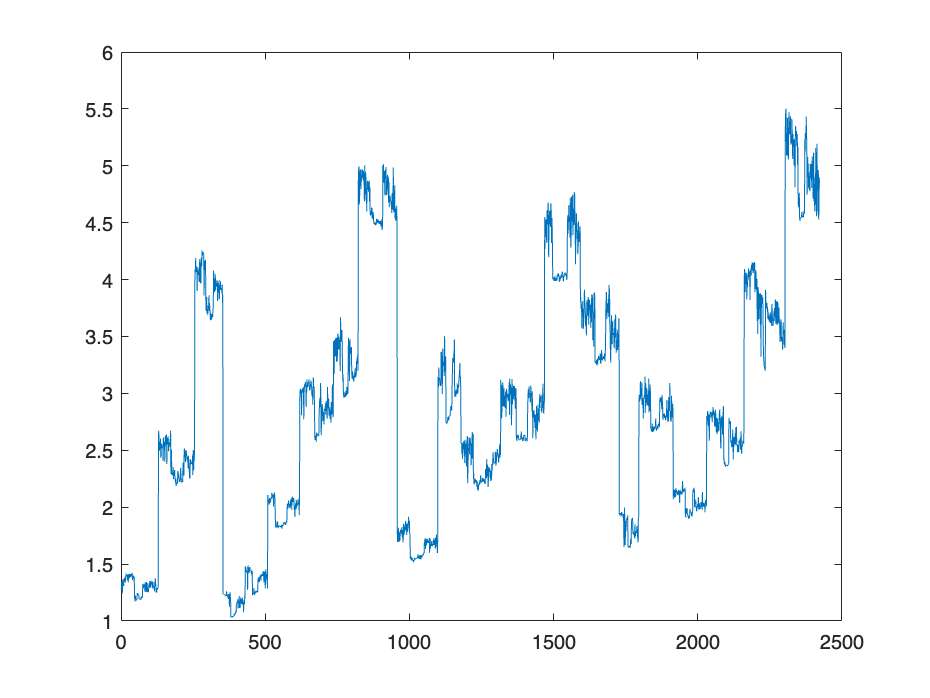

States_csv = 'Sleep_states_1019.csv'

lft_csv = 'Lifetime_1019.csv'

intensity_csv = 'Intensity_1019.csv'

length1 = 29

length2 = 46

length3 = 26

length1 = 18

length2 = 19

length3 = 41

length1 = 15

length2 = 18

length3 = 43

length1 = 49

length2 = 21

length3 = 46

length1 = 39

length2 = 51

length3 = 37

length1 = 12

length2 = 31

length3 = 26

length1 = 18

length2 = 15

length3 = 23


figure
plot(intensity_all)

for i = 1:2
    mouse_name = convertStringsToChars(Mouse_ID(i));
    eval(['intensity1 = intensity_', mouse_name, '_1;'])
    eval(['intensity2 = intensity_', mouse_name, '_2;'])
    eval(['intensity3 = intensity_', mouse_name, '_3;'])
    eval(['intensity4 = intensity_', mouse_name, '_4;'])
    
    eval(['lft1 = lft_', mouse_name, '_1;'])
    eval(['lft2 = lft_', mouse_name, '_2;'])
    eval(['lft3 = lft_', mouse_name, '_3;'])
    eval(['lft4 = lft_', mouse_name, '_4;'])

    length1 = length(intensity1)
    length2 = length(intensity2)
    length3 = length(intensity3)
    length4 = length(intensity4)

    b_intensity = NaN(100, 4);
    b_lft = NaN(100, 4);

    b_intensity(1:length1,1) = intensity1;
    b_intensity(1:length4,2) = intensity4;
    b_intensity(1:length2,3) = intensity2;
    b_intensity(1:length3,4) = intensity3;

    b_lft(1:length1,1) = lft1;
    b_lft(1:length4,2) = lft4;
    b_lft(1:length2,3) = lft2;
    b_lft(1:length3,4) = lft3;
    
    eval(['b_intensity_',mouse_name, '=b_intensity;'])
    eval(['b_lft_',mouse_name, '=b_lft;'])
end

length1 = 50

length2 = 32

length3 = 2

length4 = 18

length1 = 29

length2 = 32

length3 = 7

length4 = 10